# Problem 4

Run a discrete-time SIR model on a graph from the previous item starting from a single infected node. Assume that each infecting node remians infecting for one timestep. Plot the fraction of infecting node v.s. time. Repeat 100 times. Make a prediction for how the duration of the epidemic scales with the number of nodes in teh graph. What is the relationship between this SIR model and the BFS?

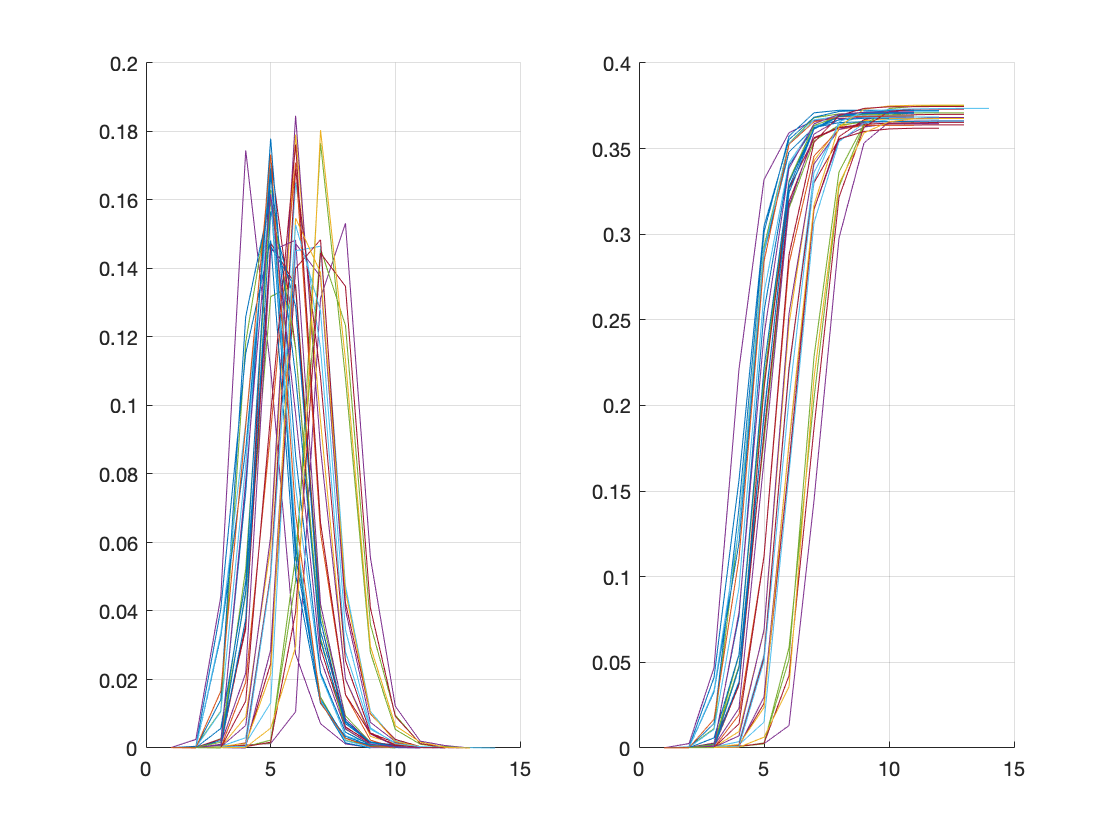

rng('default')
n = 10^4;
a = 2.2;
T = 0.4;
rounds = 100;

figure;
win1 = subplot(1,2,1);
win2 = subplot(1,2,2);
grid(win1,'on'); grid(win2,'on'); 
hold(win1,'on'); hold(win2,'on');

for r = 1:rounds
    % make power-law random graph
    [~,edges,~,~] = MakePowerLawRandomGraph(n,a);
    % fraction of nodes affected by epidemic
    infected_e = randperm(length(edges),round(T*length(edges)));
    edgelist = edges(infected_e,:);
    sz = max(edgelist(:));
    G_ = sparse([edgelist(:,1);edgelist(:,2)], ...
        [edgelist(:,2);edgelist(:,1)],1,sz,sz);
    G = full(G_);
    % find an infected node
    first = randperm(n,1);
    n_infecting = [1];
    infected = [first];
    infecting = [first];
    while ~isempty(infecting)
        newly_infected = [];
        for i = 1:length(infecting)
            cur = infecting(i);
            neighbors = find(G(cur,:));
            newly_infected = union(newly_infected,neighbors);
        end
        infecting = setdiff(newly_infected,infected);
        infected = union(infected,newly_infected);
        n_infecting = [n_infecting length(infecting)];
    end
    plot(win1, 1:length(n_infecting), n_infecting/n);
    plot(win2, 1:length(n_infecting), cumsum(n_infecting/n));
end

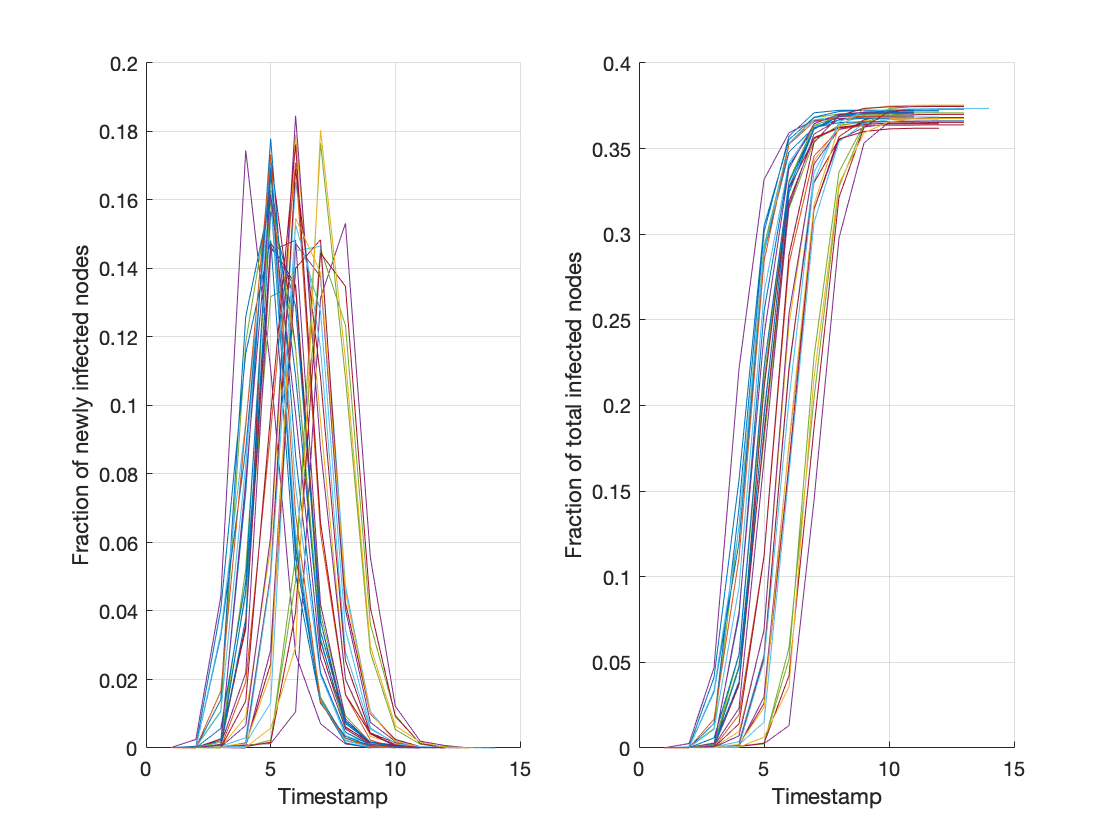

xlabel(win1,'Timestamp');
xlabel(win2,'Timestamp');
ylabel(win1,'Fraction of newly infected nodes');
ylabel(win2,'Fraction of total infected nodes');